Init

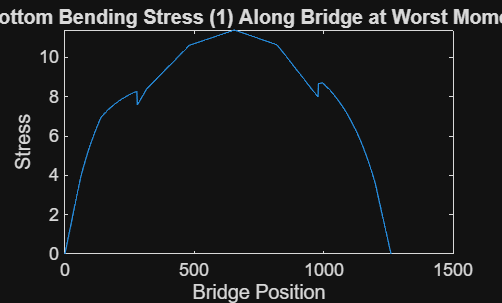

clear
clc
hold off

Constant

c = get_constants;

Shear and Moment

function [reaction_a,reaction_b] = reaction_forces(train_distance,train_load)
    % given the start of the train is x m from the left,
    % return the reaction forces at each support.
    
    % this only concerns vertical forces, since no
    % horizontal load is applied.
    
    % constraints: 0 <= x <= length - length of train
    c = get_constants();
    
    train_moments_a = train_distance .* train_load;
    reaction_b = sum(train_moments_a) / c.LENGTH;
    reaction_a = sum(train_load) - reaction_b;
end

function [V,M] = shear_and_moment(x,train_position)
    c = get_constants();

    train_distance = c.TRAIN_DIM;
    load_factor = c.LOAD_FACTOR;
    if (load_factor == -1)
        train_load = c.TRAIN_LOAD_1;
    else
        train_load = load_factor * c.TRAIN_LOAD_2;
    end

    cumulative_distances = cumsum(train_distance(1:end-1)) + train_position;
    [reaction_a, reaction_b] = reaction_forces(cumulative_distances,train_load);

    % SFD
    SFD_forces = [reaction_a -train_load reaction_b];
    SFD_net_forces = cumsum(SFD_forces);
    force_distances = [0 cumulative_distances c.LENGTH];

    SFD = [force_distances; SFD_net_forces];

    % BMD

    distance_intervals = abs(force_distances(2:end) - force_distances(1:end-1));
    BMD_moments = SFD_net_forces(1:end-1) .* distance_intervals;
    BMD_net_moments = cumsum(BMD_moments);

    BMD = [force_distances;[0,BMD_net_moments]];

    %remove dupes (horrible fix also but whatever
    [force_distances_u, ~, idx] = unique(force_distances, 'stable');
    lastIdx = accumarray(idx(:), (1:numel(idx)).', [], @max);
    % evaluated (i know this whole function computationally SUCKS but its easier)
    V = interp1(force_distances_u, SFD(2,lastIdx), x, 'previous', 'extrap');
    M = interp1(force_distances_u, BMD(2,lastIdx), x, 'linear', 'extrap');
end


Moment of Inertia

function height = h(x, min_height, max_height)
    if 0 <= x && x < 60 || 1200 <= x
        height = min_height;
    elseif 60 <= x && x < 280
        height = min_height + (max_height-min_height)/(280 - 60) * (x - 60);
    elseif 280 <= x && x < 980
        height = max_height;
    elseif 980 <= x && x < 1200
        height = max_height - (max_height-min_height)/(280 - 60) * (x - 980);
    end
end

function thickness = t(x,lower_amnt,upper_amnt)
    c = get_constants();
    if 0 <= x && x < 280 || 980 <= x
        thickness = c.STANDARD_WIDTH * lower_amnt;
    else
        thickness = c.STANDARD_WIDTH * upper_amnt;
    end
end

function I = get_moment_of_inertia(x, instead_centroid)
    % proportional for now
    % define a matrix containing info such that
    arguments
        x double
        instead_centroid = 0
    end

    c = get_constants();

    parts = ["top flange"; "left web"; "right web"; "bottom flange"];
    height = h(x,c.MIN_HEIGHT,c.MAX_HEIGHT);

    web_area = c.STANDARD_WIDTH*(height-t(x,2,3));
    areas = [100*t(x,1,2),web_area,web_area,100*c.STANDARD_WIDTH];
    centroids = [height-.5*t(x,1,2),c.STANDARD_WIDTH + 0.5*(height - t(x,2,3)),c.STANDARD_WIDTH + 0.5*(height - t(x,2,3)),.5*c.STANDARD_WIDTH];

    centroid = sum(areas.*centroids)/sum(areas);
    distances = abs(centroids-centroid);

    parallel_axes = areas .* (distances.^2);
    Is = (1/12) * [100 c.STANDARD_WIDTH c.STANDARD_WIDTH 100] .* ([t(x,1,2) height-t(x,2,3) height-t(x,2,3) c.STANDARD_WIDTH].^3);
    I = sum(Is) + sum(parallel_axes);

    if instead_centroid == 1 % might be the worst thing I've ever written but oh well
        I = centroid;
    end
end

Bending Stress

function [bottom_stress,top_stress] = bending_stress(x, train_position)
    c = get_constants();
    [~,M] = shear_and_moment(x, train_position);

    I = get_moment_of_inertia(x);
    ys = [get_moment_of_inertia(x,1) abs(h(x, c.MIN_HEIGHT, c.MAX_HEIGHT) - get_moment_of_inertia(x,1))];
    stresses = M * ys / I;
    bottom_stress = stresses(1);
    top_stress = stresses(2);
end

Tests

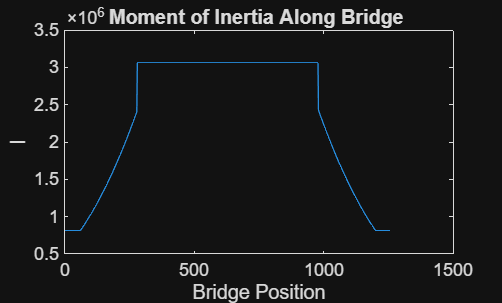

steps = 0:2:1260;
plot(steps,arrayfun(@get_moment_of_inertia,steps))
title('Moment of Inertia Along Bridge ')
xlabel("Bridge Position")
ylabel("I")
hold off

Optimization

max_bottom_bending_stress = [0 0 0]; % [i,bridge_pos,value]
max_top_bending_stress = [0 0 0]; % [i,value]
train_positions = 0:1:300;
for i = train_positions
    [bottom_bending_stress, top_bending_stress] = arrayfun(@(x) bending_stress(x, i),steps);

    [bottomMax, bottomIdx] = max(bottom_bending_stress);
    [topMax, topIdx] = max(top_bending_stress);

    if bottomMax > max_bottom_bending_stress(3)
        max_bottom_bending_stress = [i, steps(bottomIdx), bottomMax];
    end

    if topMax > max_top_bending_stress(3)
        max_top_bending_stress = [i, steps(topIdx), topMax];
    end
end
disp('bottom');

bottom


fprintf('train pos: %g, bridge pos: %g, stress: %g\n', max_bottom_bending_stress(1), max_bottom_bending_stress(2), max_bottom_bending_stress(3));

train pos: 88, bridge pos: 656, stress: 11.3953


disp('top');

top


fprintf('train pos: %g, bridge pos: %g, stress: %g\n', max_top_bending_stress(1), max_top_bending_stress(2), max_top_bending_stress(3));

train pos: 248, bridge pos: 980, stress: 8.89461


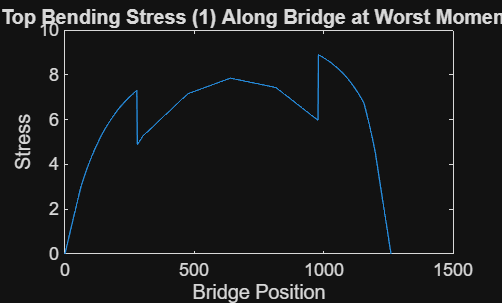



[~,top_bending_stress] = arrayfun(@(x) bending_stress(x, max_top_bending_stress(1)),steps);
plot(steps,top_bending_stress)
title('Top Bending Stress (1) Along Bridge at Worst Moment ')
xlabel("Bridge Position")
ylabel("Stress")


bottom_bending_stress = arrayfun(@(x) bending_stress(x, max_bottom_bending_stress(1)),steps);
plot(steps,bottom_bending_stress)
title('Bottom Bending Stress (1) Along Bridge at Worst Moment ')
xlabel("Bridge Position")
ylabel("Stress")